## Forward modeling of 3D gravity anomalies using high-order Gaussian quadrature 

*Copyright © 2024 by Central South University*

*__________________________________________*

`Coding: UTF - 8`

Programme written by Yaokun Yang. 

For more imformation, submit an issue or contact by email

[yangyaokun@csu.edu.cn](http://yangyaokun@csu.edu.cn)

Please read the README.md before use.

*__________________________________________*

### Add source and testfile to PATH

addpath("Source\")
addpath("Test\")

### Gravity anomaly calculation

First define a array model, and then call the function `CuboidGravity` to calculate the gravity anomaly.

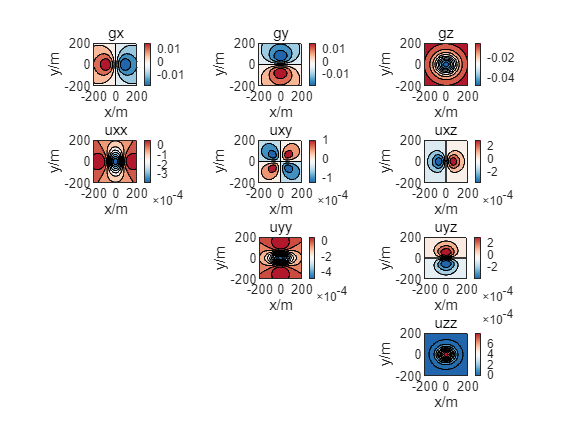

% model = [a1,a2,b1,b2,c1,c2,density]
model = [-50,50,-50,50,-150,-50,1000];

area = ObservationPlane(model);

v = CuboidGravity_GaussLegendre(model);

ContourGravity(area,v);